% Clear workspace and command window
clear; clc;

% Define symbolic variables for the joint angles
syms q1 q2 q3 q4 q5 q6 real

% Define the DH parameters from the table
% Columns are: [alpha, a, theta, d]
% Note: Constants in degrees are converted to radians (e.g., -90 deg = -pi/2)
DH = [
   -pi/2,   0,      q1-pi/2,    110.5;   % i = 1
   -pi/2,   23.42,  q2 - pi/2,  0;       % i = 2
    0,      180,    q3,         0;       % i = 3
   -pi/2,   43.5,   q4,         176.35;  % i = 4
    pi/2,   0,      q5,         0;       % i = 5
   -pi/2,   0,      q6,         0;       % i = 6
    0,      0,     -pi/2,       100     % i = ee
];

% Initialize the base-to-end-effector transformation matrix as a 4x4 Identity matrix
T0_ee = eye(4);

% Cell array to store individual matrices if you want to inspect them later
T_all = cell(1, 7);
T_0_i = cell(1, 6);

fprintf('Calculating individual transformation matrices...\n');

Calculating individual transformation matrices...



for i = 1:size(DH, 1)
    alpha = DH(i, 1);
    a     = DH(i, 2)/1000;
    theta = DH(i, 3);
    d     = DH(i, 4)/1000;
    
    % Standard DH Transformation Matrix Formula
    T_i = [ cos(theta),             -sin(theta),              0,            a;
            sin(theta)*cos(alpha),   cos(theta)*cos(alpha),  -sin(alpha),  -d*sin(alpha);
            sin(theta)*sin(alpha),   cos(theta)*sin(alpha),   cos(alpha),   d*cos(alpha);
            0,                       0,                       0,            1];
            
    % Simplify the current matrix to evaluate sin/cos of constants (like pi/2)
    T_i = simplify(T_i);
    T_all{i} = T_i;
    
    % Post-multiply to accumulate the total transformation
    T0_ee = T0_ee * T_i;
    T_0_i{i} = simplify(T0_ee);
end

fprintf('Simplifying final transformation matrix T0_ee (this may take a moment)...\n');

Simplifying final transformation matrix T0_ee (this may take a moment)...


% Final simplification to combine trig terms
T0_ee = simplify(T0_ee);

% Display the result
disp('Final Transformation Matrix T0_ee:');

Final Transformation Matrix T0_ee:


disp(T0_ee);

q1_val = 0; q1_val = deg2rad(q1_val);
q2_val = 0; q2_val = deg2rad(q2_val);
q3_val = 0; q3_val = deg2rad(q3_val);
q4_val = 0; q4_val = deg2rad(q4_val);
q5_val = 0; q5_val = deg2rad(q5_val);
q6_val = 0; q6_val = deg2rad(q6_val);


res = subs (T0_ee,[q1,q2,q3,q4,q5,q6],[q1_val, q2_val, q3_val, q4_val, q5_val, q6_val]);
res = double (res)

res =     1.0000         0         0         0
         0    1.0000         0    0.3340
         0         0    1.0000    0.2998
         0         0         0    1.0000




R = res(1:3, 1:3);
angles_rad = rotm2eul(R, 'XYZ');

% Extract individual angles in radians
Rx_rad = angles_rad(1);
Ry_rad = angles_rad(2);
Rz_rad = angles_rad(3);

% Convert back to degrees if needed
Rx_deg = rad2deg(Rx_rad);
Ry_deg = rad2deg(Ry_rad);
Rz_deg = rad2deg(Rz_rad);

fprintf('Rx: %.2f deg, Ry: %.2f deg, Rz: %.2f deg\n', Rx_deg, Ry_deg, Rz_deg);

Rx: -0.00 deg, Ry: 0.00 deg, Rz: -0.00 deg


%% METHOD 1: 3D Stick Model (Using your exact matrices)
fprintf('Generating 3D Stick Model...\n');

Generating 3D Stick Model...


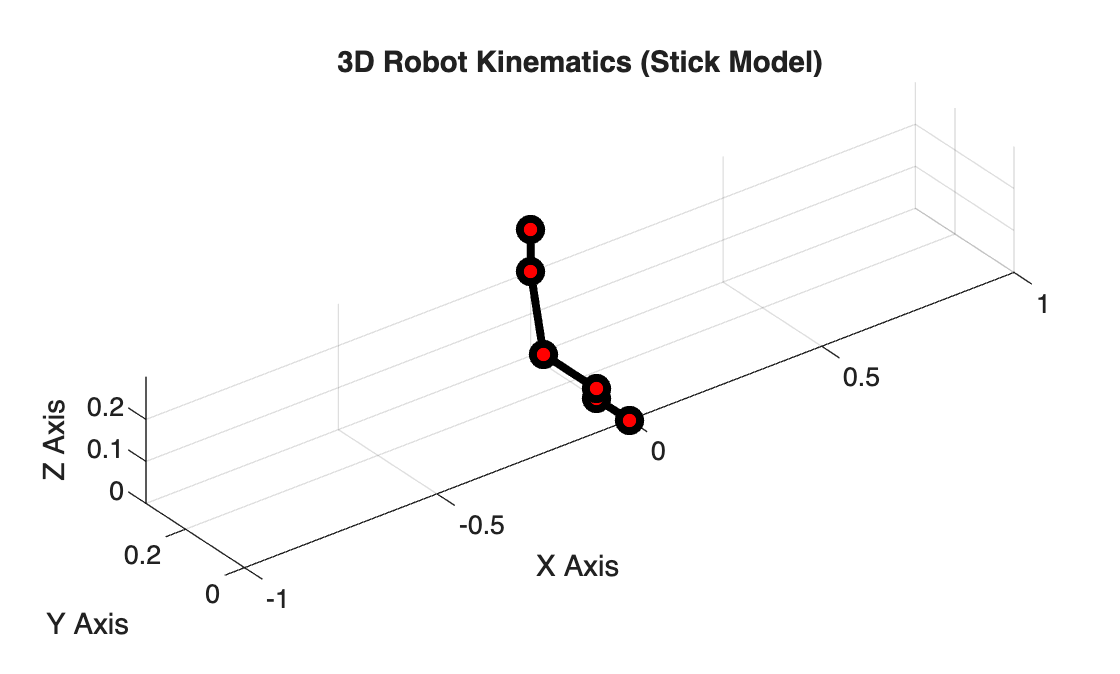


% Initialize an array to hold the [X; Y; Z] positions of each frame
% 8 columns total (1 for the Base + 7 frames from your DH table)
positions = zeros(3, 8); 
T_current = eye(4);

% Base is at origin
positions(:, 1) = [0; 0; 0]; 

for i = 1:7
    % 1. Substitute your numeric joint values into the saved symbolic matrices
    T_i_sym = subs(T_all{i}, [q1,q2,q3,q4,q5,q6], [q1_val, q2_val, q3_val, q4_val, q5_val, q6_val]);
    
    % 2. Convert to standard double precision numbers
    T_i_num = double(T_i_sym);
    
    % 3. Post-multiply to get the position relative to the base
    T_current = T_current * T_i_num;
    
    % 4. Extract the translation vector (the first 3 rows of the 4th column)
    positions(:, i+1) = T_current(1:3, 4);
end

% Plotting the robot as a 3D line
figure('Name', 'Robot Stick Model', 'Color', 'w');
plot3(positions(1,:), positions(2,:), positions(3,:), '-o', ...
    'LineWidth', 3, 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'Color', 'k');
grid on;
axis equal; % CRITICAL: ensures the robot proportions aren't distorted
xlabel('X Axis'); ylabel('Y Axis'); zlabel('Z Axis');
title('3D Robot Kinematics (Stick Model)');

% %% METHOD 2: Robotics System Toolbox 3D Plot
% fprintf('Generating Robotics System Toolbox 3D Model...\n');
% 
% % Create a blank robot tree
% robot = rigidBodyTree('DataFormat', 'column');
% 
% % Rearrange your DH parameters to match MATLAB's 'mdh' order: [a, alpha, d, theta_offset]
% % Note: We ONLY put the constant offsets here. The joint variables (q) are handled later.
% dh_params_mdh = [
%     0,      0,      110.5,   0;      % Joint 1
%     23.42, -pi/2,   0,      -pi/2;   % Joint 2 (Note the -pi/2 offset from your table)
%     180,    0,      0,       0;      % Joint 3
%     43.5,  -pi/2,   176.35,  0;      % Joint 4
%     0,      pi/2,   0,       0;      % Joint 5
%     0,     -pi/2,   0,       0;      % Joint 6
% ];
% 
% % Build the first 6 revolute joints
% for i = 1:6
%     body = rigidBody(['link', num2str(i)]);
%     joint = rigidBodyJoint(['joint', num2str(i)], 'revolute');
% 
%     % Attach DH parameters using the Modified DH convention ('mdh')
%     setFixedTransform(joint, dh_params_mdh(i, :), 'mdh');
%     body.Joint = joint;
% 
%     if i == 1
%         addBody(robot, body, robot.BaseName);
%     else
%         addBody(robot, body, ['link', num2str(i-1)]);
%     end
% end
% 
% % Add the 7th frame (End-Effector) which is a fixed frame in your table
% eeBody = rigidBody('end_effector');
% eeJoint = rigidBodyJoint('ee_joint', 'fixed');
% % Mapping your 7th row: a=0, alpha=0, d=62.8, theta=-pi/2
% setFixedTransform(eeJoint, [0, 0, 62.8, -pi/2], 'mdh');
% eeBody.Joint = eeJoint;
% addBody(robot, eeBody, 'link6');
% 
% % Define the robot's current configuration vector using your values
% config = [q1_val; q2_val; q3_val; q4_val; q5_val; q6_val];
% 
% % Visualize the robot
% figure('Name', 'Rigid Body Tree Model', 'Color', 'w');
% show(robot, config, 'PreservePlot', false, 'Frames', 'on');
% title('Interactive 3D Robot Model');
% view([45, 30]); % Set a nice isometric viewing angle

%% Build the Geometric Jacobian
fprintf('Calculating the Symbolic Jacobian...\n');

Calculating the Symbolic Jacobian...



% Initialize an empty 6x6 symbolic Jacobian matrix
J = sym(zeros(6, 6));

% We need a running transformation matrix to track frame (i-1)
% Start at the base (Identity matrix)
T_prev = eye(4);

% Extract the final end-effector position from your completed T0_ee
p_ee = T0_ee(1:3, 4);

% Loop through only the 6 active joints (ignoring the fixed 7th ee frame for the columns)
for i = 1:6
    % 1. Extract the Z-axis vector of the previous frame
    % This is the 3rd column of the rotation matrix part of T_prev
    z_prev = T_prev(1:3, 3);
    
    % 2. Extract the origin position of the previous frame
    % This is the 4th column of the translation part of T_prev
    p_prev = T_prev(1:3, 4);
    
    % 3. Calculate Linear Velocity portion (Top 3 rows) using the cross product
    J(1:3, i) = cross(z_prev, (p_ee - p_prev));
    
    % 4. Calculate Angular Velocity portion (Bottom 3 rows)
    % For a revolute joint, this is simply the axis of rotation
    J(4:6, i) = z_prev;
    
    % 5. Update T_prev to the current frame for the next loop iteration
    T_prev = T_prev * T_all{i};
end

fprintf('Simplifying the Jacobian (this may take a minute)...\n');

Simplifying the Jacobian (this may take a minute)...


J = simplify(J);

disp('Symbolic Jacobian Matrix (J):');

Symbolic Jacobian Matrix (J):


disp(J);


%% Evaluate the Jacobian with your specific numbers
% Plug your numeric joint angles into the symbolic Jacobian
anaz

Numeric Jacobian Matrix for the current pose:


   -0.3340    0.2998         0         0         0         0
         0         0   -0.2763   -0.2763         0   -0.1000
         0         0    0.2235    0.0435         0         0
         0         0    1.0000    1.0000         0    1.0000
         0    1.0000         0         0         0         0
    1.0000         0         0         0    1.0000         0



c = 0.1

c = 0.1000

inv(J_numeric)

ans =    -2.9940         0         0         0    0.8975    0.0000
         0         0         0         0    1.0000         0
         0    1.3704    5.5556    0.1370         0         0
         0   -7.0409   -5.5556   -0.7041         0         0
    2.9940         0         0         0   -0.8975    1.0000
         0    5.6705         0    1.5671         0         0


J_dls = J_numeric*transpose(J_numeric) + c*c * eye(6)

J_dls =     0.2114         0         0         0    0.2998   -0.3340
         0    0.1727   -0.0738   -0.6527         0         0
         0   -0.0738    0.0618    0.2670         0         0
         0   -0.6527    0.2670    3.0100         0         0
    0.2998         0         0         0    1.0100         0
   -0.3340         0         0         0         0    2.0100


J_dls = inv(J_dls) * transpose(J_numeric)

J_dls =    -4.9892   -0.2482         0    2.4822         0   10.5041
   12.1909   -6.7011    4.1026   24.2486   40.6676         0
    5.0757   -9.3894    7.4638   33.9765   16.9320         0
    2.1933   -0.7120    0.2420    2.5765    7.3166         0
    1.4808    0.0737         0   -0.7367         0   -2.1275
   -0.8290   -0.0910         0    0.9100         0    1.7455
